# Create and Customize Polar Scatter Plots

`polarscatter` plots a set of angles versus a set of radii and displays a circular marker at each data point. The angle and radius inputs must be vectors of the same length where the angle is specified in radians.

### Create Angle and Radius Vectors

Define an evenly spaced angle vector that spans the entire circle. Create a radius vector `r `from the angles such that a spiral will be formed.

th = linspace(0,2*pi,50);
r = 0.005*(th * 180/pi)/10;

### Basic Polar Scatter Plot

Plot the two vectors to form the spiral pattern as the value of each radius increases with theta.

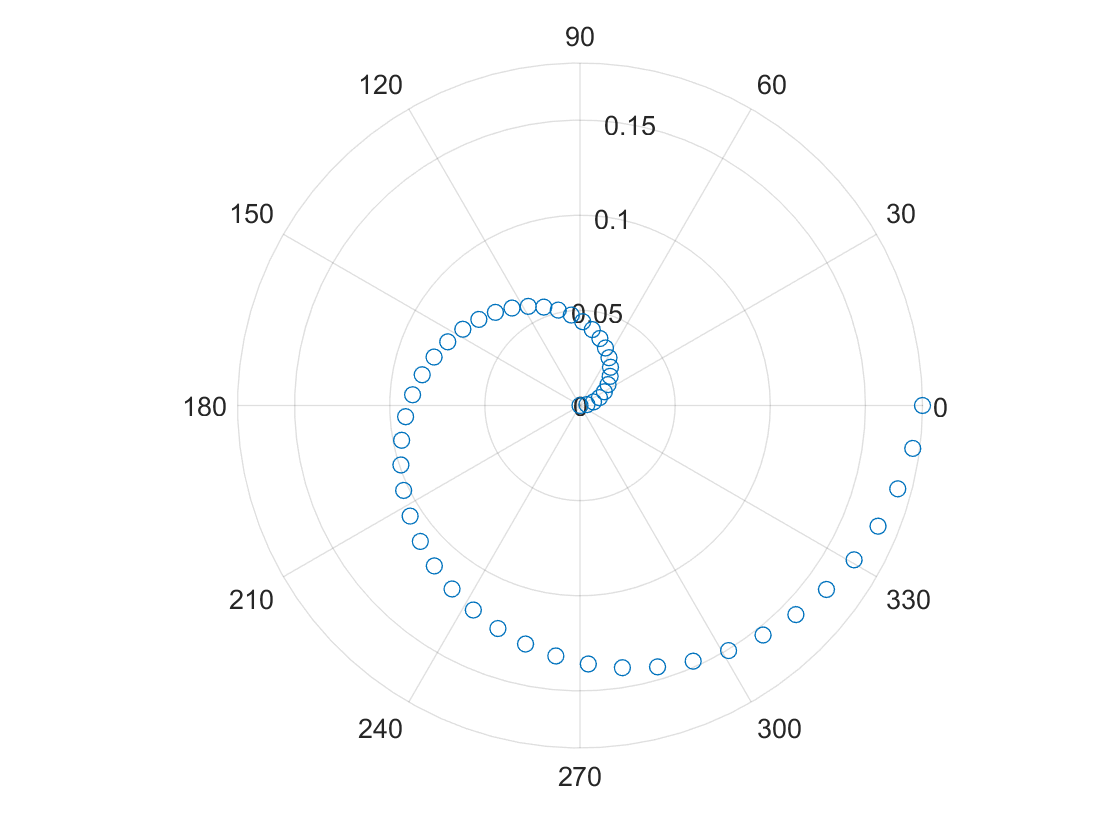

polarscatter(th,r)

## Customizations

### Specify Point Appearance Options

The marker used to plot each point can be modified to adjust various properties such as the color, size, symbol. These properties are set through the plot command by referencing name value pairs of *MarkerFaceColor*, *SizeData*, and *Marker*. Color options can be defined either by a color identifying character or by an RGB triplet vector. The marker size is based on a scalar value while the marker symbol is defined by a recognized marker specification. Each point can be filled by specifying the `filled `parameter after the data in the function call.  A new data set of random points over angles from $\frac{\pi }{6}$ to $2\pi$ will be used and adjusted to offer different appearance options. 

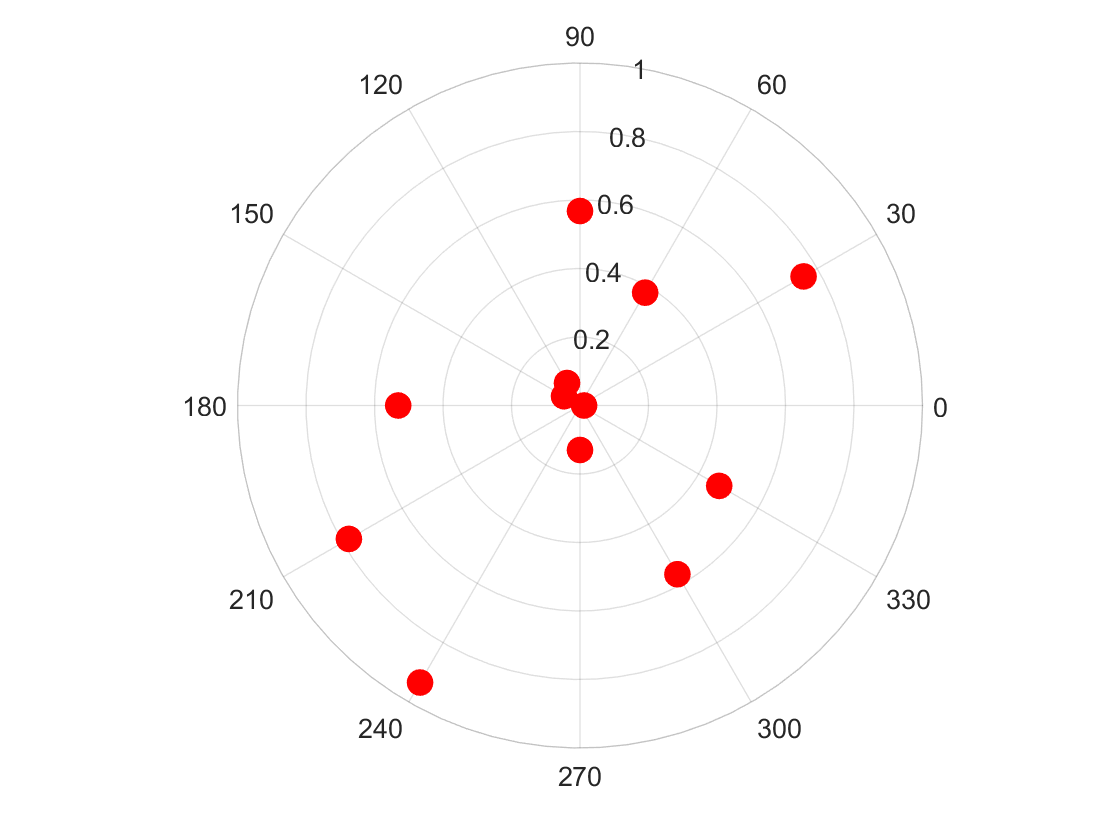

Color = "red";
MarkerSize = 100;
MarkerType = 'o';

th = pi/6:pi/6:2*pi;
r = rand(12,1);
ps = polarscatter(th,r,'filled',...         % Specify fill options
     "MarkerFaceColor",Color,...            % Specify point color
     "SizeData",MarkerSize,...              % Specify point size
     "Marker",MarkerType);                  % Specify marker symbol

### Add Axis Labels

In some cases, specific angles and angle ranges have spatial significance that needs to be specified. For example, in the case of a radar display the $0,90,180,\;$and $270$ degree positions correlate to directions on a compas. These angle axes can be titled using the *thetaticks* command after creating the plot. To make it more like a radar

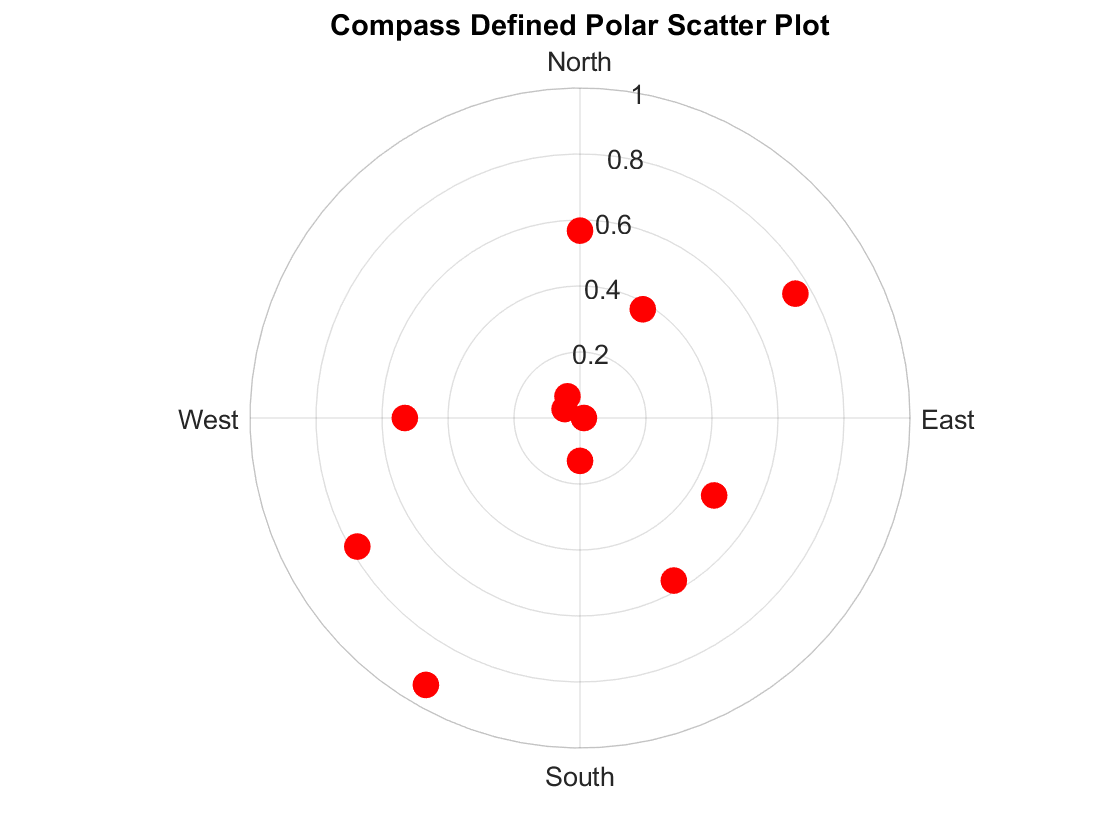

thetaticks([0 90 180 270])
thetaticklabels({'East','North','West','South'})
title('Compass Defined Polar Scatter Plot')

## Additional Information

### Get All Polar Scatter Properties

Graphics objects in MATLAB have many properties. To see all the properties of the polar scatter plot, uncomment the following code

% get(ps)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[polarscatter](https://www.mathworks.com/help/matlab/ref/polarscatter.html?searchHighlight=polarscatter&s_tid=srchtitle)